# Bayesian Decoding and Place Field Esimation Sandbox

# Pho Hale, 2021-11-01 

% Load the data:
addpath(genpath('src'))
% file_path = '../../EichenbaumData/AJF023/EF3/AJF023EF3SpksEvs.mat';
% [spikes, X, t, sample_rate] = load_data_xy(file_path);
%{
spikes: 1xK cell array of spiking data, where K is the number of units:
            spikes{1}: vector of timestamps for each spike at unit 1.
            spikes{2}: vector of timestamps for each spike at unit 2.
            ...
        X: NxM array of ground-truth stimulus features, where N is the number of
        stimulus dimensions and M is the number of sampling timestamps.

        t: 1xM array of timestamps for ground-truth stimulus sampling.
        sample_rate: sample rate of ground-truth data.
%}
% experimentName = 'RoyMaze1';
% experimentName = 'Roy-maze1';
% experimentName = 'KevinMaze1';
experimentName = 'Kevin-maze1';
% '/Volumes/iNeo/Data/Rotation_3_Kamran Diba Lab/DataProcessingProject/Hiro_Datasets/analysesResults_02-Nov-2021/Kevin-maze1'
% smartload('/Users/pho/repo/NGP Rotations Repos/PhoDibaLab_DataAnalysis/Data/Rotation_3_Kamran Diba Lab/DataProcessingProject/Hiro_Datasets/Results/PhoResults_Expt1_RoyMaze1_v7_3.mat', ...
%     'active_processing', 'general_results', 'num_of_electrodes', 'processing_config', 'results_array', 'source_data', 'timesteps_array');

parentFolder = '/Volumes/iNeo/Data/Rotation_3_Kamran Diba Lab/DataProcessingProject/Hiro_Datasets/analysesResults_02-Nov-2021/';
smartload([parentFolder experimentName '/toAddVariables.mat'], ...
    'behavior', 'fileinfo', '-f');

smartload - All variables already exist in the base workspace.

smartload(...): loading data from /Volumes/iNeo/Data/Rotation_3_Kamran Diba Lab/DataProcessingProject/Hiro_Datasets/analysesResults_02-Nov-2021/Kevin-maze1/toAddVariables.mat... Please wait...
	 done.


smartload([parentFolder experimentName '/PlaceFields/biDirectional.mat'], ...
    'PF_sorted_biDir', 'conslapsRatio_biDir', 'diffWithAvg_biDir', 'runTemplate_biDir', 'spatialInfo_biDir', 'spatialTunings_biDir', 'positionBinningInfo_biDir');

smartload - All variables already exist in the base workspace.The file will not be loaded


smartload([parentFolder experimentName '/TrackLaps/trackLaps.mat']);

smartload - All variables already exist in the base workspace.The file will not be loaded



smartload([parentFolder experimentName '/spikesVariables.mat']);

smartload - All variables already exist in the base workspace.The file will not be loaded



% smartload([parentFolder experimentName '/TrackLaps/trackLaps.mat'], ...
%     );
%     'laps', 'lapsStruct', 'lapsTable', 'positionTable', 'currMazeShape', 'occupancyInfo', 'trackInfo');

% /Volumes/iNeo/Data/Rotation_3_Kamran Diba Lab/DataProcessingProject/Hiro_Datasets/analysesResults_02-Nov-2021/Kevin-maze1/TrackLaps/trackLaps.mat

% 68368.7142280000 % active_processing format (seconds, absolute)
% 68368714228.0000 % fileinfo.tbegin (??, absolute)

% fileinfo.tbegin -> active_processing format: fileinfo.tbegin ./ 1e6

% % t_rel is aligned with the timestamps in the active_processing.position_table's timestamp column
% t_rel = ((fileinfo.xyt2(:, 2)-fileinfo.tbegin) ./ 1e6); % Convert to relative timestamps since start
% % TimestampPosition = t_rel;
% AnimalPosition = fileinfo.xyt2(:,1);

## Looks like everything in source_data.spikes is already in absolute timestamps:

% behavior.time(1,1) % get the absolute experiment start time (68368714228.0000)
% 
% % spikes = {source_data.spikes.RoyMaze1.time};
% spikes = fnCellContentsTranpose(active_processing.spikes.time)';
% % Absolute timestamp version are available here: source_data.position.RoyMaze1.t
% 
% % X = spikeStruct.linearPos';
% % t = spikeStruct.t';
% 
% X = fileinfo.xyt2(:,1)';
% temp.validIndicies = ~isnan(X);
% 
% % t_rel is aligned with the timestamps in the active_processing.position_table's timestamp column
% t = ((fileinfo.xyt2(:, 2)-fileinfo.tbegin) ./ 1e6)'; % Convert to relative timestamps since start
% 
% 
% X = X(temp.validIndicies);
% t = t(temp.validIndicies);
% lapNumber = fileinfo.xyt2(temp.validIndicies, 3);
% 
% % Lap-only indicies
% 
% %% laps are represented in absolute timestamps, convert to experiment relative timestamps
%     % outputs will be aligned with the timestamps in the active_processing.position_table's timestamp column
% lapsInfo.laps(:, 1:2) = ((lapsInfo.laps(:, 1:2) - fileinfo.tbegin) ./ 1e6); % Convert to relative timestamps since start
% lapsInfo.numTotalLaps = size(lapsInfo.laps, 1); 
% 
% temp.lapOnlyIndicies = find(lapNumber > 0); 
% 
% % If I want to only include the data from the laps, do this:
% X = X(temp.lapOnlyIndicies);
% t = t(temp.lapOnlyIndicies);
% lapNumber = lapNumber(temp.lapOnlyIndicies);
% 
% unique_lap_numbers = unique(lapNumber, 'stable');
% t_start = lapsInfo.laps(unique_lap_numbers, 1); % Lap Starts
% t_end = lapsInfo.laps(unique_lap_numbers, 2); % Lap Ends
% 
% % durations: (t_end - t_start)
% 
% % ([t_end; 0] - [ 0; t_start]) % last entry is negative
% unique_lap_numbers = unique_lap_numbers(end-1);
% t_start = t_start(end-1); % Lap Starts
% t_end = t_end(end-1); % Lap Ends
% 
% % [sortedLapNumbers, sortedLapNumberIndicies] = sort(t_start, 1, 'ascend');
% % t_start = lapsInfo.laps(sortedLapNumberIndicies, 1); % Lap Starts
% % t_end = lapsInfo.laps(sortedLapNumberIndicies, 2); % Lap Ends
% 
% %spikeStruct.t contains absolute timestamps, convert to relative timestamps
% sample_rate = 1/source_data.basics.RoyMaze1.posSampleRate; % 1 / 29.970;

%%% New mode:
%% Pho's comments:
% Looks like I need some position data in X

% spikes = {source_data.spikes.RoyMaze1.time};
spikes = fnCellContentsTranpose(active_processing.spikes.time)';
% Absolute timestamp version are available here: source_data.position.RoyMaze1.t


% t_rel is aligned with the timestamps in the active_processing.position_table's timestamp column
% t = ((fileinfo.xyt2(:, 2)-fileinfo.tbegin) ./ 1e6)'; % Convert to relative timestamps since start
positionTable.t_rel = ((positionTable.t - fileinfo.tbegin) ./ 1e6); % Convert to relative timestamps since start


X = positionTable.linearPos';
t = positionTable.t_rel';
% temp.validIndicies = ~isnan(X);

sample_rate = fileinfo.Fs;


%% Build the tuning curves.
% t_start = t(1);
% t_end = t(end);

% t_start = behavior.time(2,1);
% t_end = behavior.time(2,2);

% Track Only:
t_start = active_processing.behavioral_epochs.start_seconds(2);
t_end = active_processing.behavioral_epochs.end_seconds(2);

% %% Laps Only:
% unique_lap_numbers = unique(lapNumber);
% t_start = lapsInfo.laps(unique_lap_numbers, 1); % Lap Starts
% t_end = lapsInfo.laps(unique_lap_numbers, 2); % Lap Ends

% sigma = [3 3];
% bin_size = [3 3]; % spatial bin size (cm)
%% Config 1:
% sigma = [3];
% bin_size = [3]; % spatial bin size (cm)
% f_base = 2; % base firing rate (Hz)
% min_t_occ = 0.5;

%% Config 2:
sigma = [5];
bin_size = [2]; % spatial bin size (cm)
f_base = 2; % base firing rate (Hz)
min_t_occ = 0.5;

[~,lambda] = build_tuning_curves(spikes, X, t, sample_rate, t_start, t_end, bin_size, sigma);
%{
lambda: (N+1)-dimensional array of mean firing rate for each bin,
        where the size of the first dimension is the number of units.
%}
[coords,alpha,beta] = build_tuning_curves(spikes, X, t, sample_rate, t_start, t_end, bin_size, sigma, f_base, min_t_occ);
%{
coords: N x 1 cell array of coordinate locations, where N is the number of stimulus dimensions:
            coords{1}: N-dimensional array of the coordinate position for
            each bin in stimulus dimension 1.
            coords{2}: N-dimensional array of the coordinate position for
            each bin in stimulus dimension 2.

alpha: (N+1)-dimensional array of alpha parameter for each bin,
        where the size of the first dimension is the number of units.
        
beta: N-dimensional array of beta parameter for each bin.
    
        (if f_base and min_t_occ are supplied)
%}
%% Get information content curves.
IC_curves = get_IC_curves(alpha,beta,f_base,min_t_occ);

## Save Outputs


input_variables_names = {'spikes', 'X', 't', 'sample_rate', 't_start', 't_end', 'bin_size', 'sigma', 'f_base', 'min_t_occ'};
output_variable_names = {'lambda', 'coords', 'alpha', 'beta', 'IC_curves'};

experimentIdentifier = 'KevinMaze1';
for i = 1:length(input_variables_names)
    BayesocampusResults.(experimentIdentifier).Inputs.(input_variables_names{i}) = eval(input_variables_names{i}); 
end

for i = 1:length(output_variable_names)
    BayesocampusResults.(experimentIdentifier).Outputs.(output_variable_names{i}) = eval(output_variable_names{i}); 
end

save('Bayesiocampus_Results_2021_11_01-5.mat', "BayesocampusResults")

%% Filtering Options:
filter_config.filter_included_cell_types = {};
% filter_config.filter_included_cell_types = {'pyramidal'};
% filter_config.filter_included_cell_types = {'interneurons'};
filter_config.filter_maximum_included_contamination_level = {2};
%filter_config.filter_maximum_included_contamination_level = {};

require_always_stable_units = true;
%% Get filter info for active units
[plot_outputs.filter_active_units, plot_outputs.original_unit_index] = fnFilterUnitsWithCriteria(active_processing, require_always_stable_units, filter_config.filter_included_cell_types, ...
    filter_config.filter_maximum_included_contamination_level);
temp.num_active_units = sum(plot_outputs.filter_active_units, 'all');
fprintf('Filter: Including %d of %d total units\n', temp.num_active_units, length(plot_outputs.filter_active_units));

Filter: Including 57 of 76 total units



[sortedPeakPlaces, sortedTuningCurveIndicies] = fnSortPlaceCellSpatialTuningCurves(BayesocampusResults.(experimentIdentifier).Outputs.lambda(plot_outputs.filter_active_units, :), ...
     coords{1}, plot_outputs.original_unit_index);
sortedOriginalUnitIndicies = plot_outputs.original_unit_index(sortedTuningCurveIndicies);


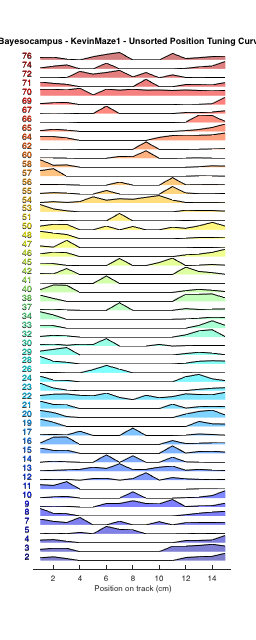

%% Plot tuning curves:
[figH, h] = fnPlotPlaceCellSpatialTunings(BayesocampusResults.(experimentIdentifier).Outputs.lambda(plot_outputs.filter_active_units, :), 'unitLabels', num2cellstr(plot_outputs.original_unit_index));
% [figH, h] = fnPlotPlaceCellSpatialTunings(BayesocampusResults.(experimentName).Outputs.alpha(plot_outputs.filter_active_units, :), 'unitLabels', num2cellstr(plot_outputs.original_unit_index));
curr_fig_name = sprintf('Bayesocampus - %s - Unsorted Position Tuning Curves', experimentIdentifier);
title(curr_fig_name)

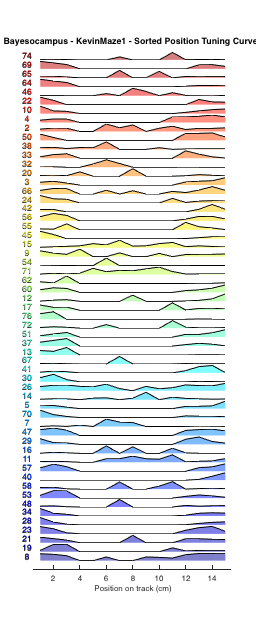

savefig(curr_fig_name);

[figH, h] = fnPlotPlaceCellSpatialTunings(BayesocampusResults.(experimentIdentifier).Outputs.lambda(sortedTuningCurveIndicies, :), 'unitLabels', num2cellstr(sortedOriginalUnitIndicies));
curr_fig_name = sprintf('Bayesocampus - %s - Sorted Position Tuning Curves', experimentIdentifier);
title(curr_fig_name)

savefig(curr_fig_name);

% coords{1} % actual x-positions
% BayesocampusResults.(experimentName).Outputs.beta(plot_outputs.filter_active_units, :)




## Interactive: %% Page through the tuning curves and information content curves.

K = size(alpha,1)

K = 76

i =87

i = 87

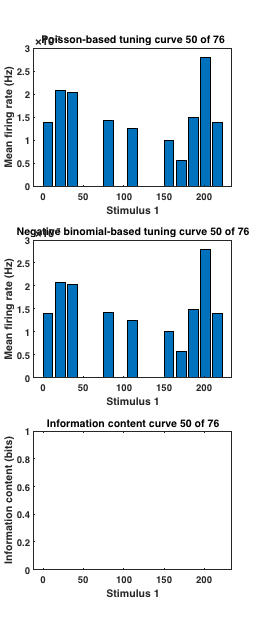

% for i = 1:K

    subplot(3,1,1);

    plot_curves('tuning_curve',coords,lambda(i,:,:));

Index in position 1 exceeds array bounds. Index must not exceed 76.

    title(sprintf('Poisson-based tuning curve %d of %d',i,K));
    subplot(3,1,2);
    plot_curves('tuning_curve',coords,alpha(i,:,:),beta);
    title(sprintf('Negative binomial-based tuning curve %d of %d',i,K));
    subplot(3,1,3);
    plot_curves('IC_curve',coords,IC_curves(i,:,:));
    title(sprintf('Information content curve %d of %d',i,K));
    
%     waitforbuttonpress;
% end


## %% Perform neural decoding.

t_0 = 1000;
t_f = 1030;
t_step = 0.25;
t_start = t_0:t_step:t_f;
t_end = (t_0:t_step:t_f) + t_step;
 
poiss_posterior = bayesian_decode(spikes,t_start,t_end,lambda);
nb_posterior = bayesian_decode(spikes,t_start,t_end,alpha,beta);


## Page through the decoded posterior across time.

M = size(nb_posterior,1);
for i = 1:M
    t = t_start(i);
    
    subplot(2,1,1);
    plot_curves('posterior',coords,poiss_posterior(i,:,:));
    title(sprintf('Poisson-based decoded posterior at t = %.2f',t));
    subplot(2,1,2);
    plot_curves('posterior',coords,nb_posterior(i,:,:));
    title(sprintf('Negative binomial-based decoded posterior at t = %.2f',t));
    
    waitforbuttonpress;
end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted